data=readtable('Copy.csv');

y=data{:,9}; %calificacion 
x=data{:,2}; %Numero de estudiante

format long 
b1=x\y;


GRAFICA

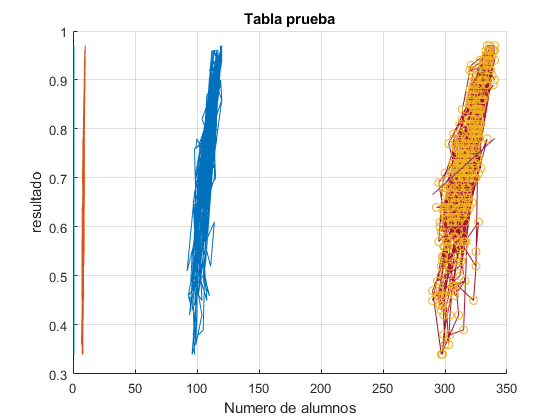

yCalc1=b1*x;
scatter(x,y)
hold on;
plot(x,yCalc1)
xlabel('Numero de alumnos');
ylabel('resultado');
title('Tabla prueba');
grid on;

Multivariable

[n,d]=size(y);

x2=data{:,3};
x3=data{:,7};

xMat=[ones(n,1) x x2 x3];

[beta, sigma,E,V]= mvregress(xMat,y)

beta =   -1.585698406666071
   0.002265957768207
   0.003112252163745
   0.146284446731057


sigma =    0.004354450025869


E =   -0.036820027496435
  -0.019025934258317
   0.095705953034597
   0.045426114133073
   0.002630386921235
   0.013726611858880
   0.069558014028622
   0.097798816344597
  -0.086346133883010
  -0.290375428036470


V =    0.011084900499357  -0.000051612969157   0.000012400627273   0.000458825955175
  -0.000051612969157   0.000000348028944  -0.000000305869185  -0.000002999421612
   0.000012400627273  -0.000000305869185   0.000001213103725  -0.000005326066508
   0.000458825955175  -0.000002999421612  -0.000005326066508   0.000123676635258


beta

beta =   -1.585698406666071
   0.002265957768207
   0.003112252163745
   0.146284446731057




plot(xMat,y)

Error using plot
Vectors must be the same length.

xlabel('Numero de alumnos');
ylabel('resultado');
title('Tabla prueba');
grid on;
